ng = 5

ng = 5

ns = 11

ns = 11

[omega_p,omega_s,Delta_p] = PS_PRJ_1_Faza_3b(ng,ns);
omega = linspace(0,pi,5000);
M = 29;

omega_p = 1.5708

omega_p = 1.5708

omega_s = 1.7203

omega_s = 1.7203

Delta_p = 0.05

Delta_p = 0.0500

Delta_s = 0.05

Delta_s = 0.0500


M1 = M

M1 = 29

M2 = M+round(M/2)

M2 = 44

M3 = 3*M+23

M3 = 110

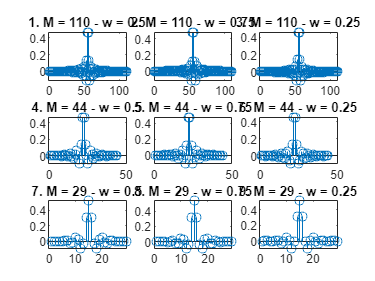


ord = [M1 M2 M3];
w = [0.25 0.5 0.75];
win1 = kaiser(M1,beta-1);
win2 = kaiser(M2,beta-1);
win3 = kaiser(M3,beta-1);

ponderi1 = zeros(3, M1);
ponderi2 = zeros(3, M2);
ponderi3 = zeros(3, M3);
spectre = zeros(3, 5000, 3);
tolerante = zeros(3, 3, 2);
oc = zeros(3,3);

for i = 1:3
    for j = 1:3
        omega_c = (1 - w(j)) * omega_p + w(j) * omega_s;
        oc(i,j) = omega_c;
        if i == 1
            h = fir1(ord(i)-1, omega_c/pi, win1);
            ponderi1(j,:) = h;
        end
        if i == 2
            h = fir1(ord(i)-1, omega_c/pi, win2);
            ponderi2(j,:) = h;
        end
        if i == 3
            h = fir1(ord(i)-1, omega_c/pi, win3);
            ponderi3(j,:) = h;
        end
        
        [Delta_pr,Delta_sr] = PS_PRJ_1_Faza_3a(h,omega_p,omega_s);

        tolerante(i, j, 1) = Delta_pr;
        tolerante(i, j, 2) = Delta_sr;

        H = freqz(h, 1, 5000);
        spectre(i, :, j) = H;
    end
end

sumtol = zeros(3, 3);
for i = 1:3
    for j = 1:3
        sumtol(i, j) = tolerante(i, j, 1) + tolerante(i, j, 2);
    end
end

%Figura 16
figure;
subplot(3,3,1);
stem(ponderi3(2,:));
title("1. M = 110 - w = 0.5");

subplot(3,3,2);
stem(ponderi3(3,:));
title("2. M = 110 - w = 0.75");

subplot(3,3,3);
stem(ponderi3(1,:));
title("3. M = 110 - w = 0.25");

subplot(3,3,4);
stem(ponderi2(2,:));
title("4. M = 44 - w = 0.5");

subplot(3,3,5);
stem(ponderi2(3,:));
title("5. M = 44 - w = 0.75");

subplot(3,3,6);
stem(ponderi2(1,:));
title("6. M = 44 - w = 0.25");

subplot(3,3,7);
stem(ponderi1(2,:));
title("7. M = 29 - w = 0.5");

subplot(3,3,8);
stem(ponderi1(3,:));
title("8. M = 29 - w = 0.75");

subplot(3,3,9);
stem(ponderi1(1,:));
title("9. M = 29 - w = 0.25");


tp = linspace(0,omega_p,5000);
ts = linspace(omega_s,pi,5000);
xpp = mag2db(1+Delta_p)*ones(size(tp));
xpm = mag2db(1-Delta_p)*ones(size(tp));
xs = mag2db(Delta_s)*ones(size(ts));

tolerante

tolerante = tolerante(:,:,1) =

    0.4099    0.3233    0.2442
    0.3633    0.2394    0.1394
    0.1826    0.0240    0.0019


tolerante(:,:,2) =

    0.2419    0.3204    0.4066
    0.1368    0.2353    0.3582
    0.0018    0.0214    0.1742


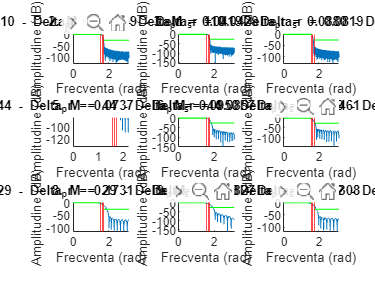


%Figura 17
figure;
subplot(3,3,1);
hold on;
plot(omega,mag2db(abs(spectre(3,:,2))));
xline([omega_p oc(3,2) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("1. M = 110 - Delta_pr = 0.0499 - Delta_sr = 0.0429");
hold off;

subplot(3,3,2);
hold on;
plot(omega,mag2db(abs(spectre(3,:,3))));
xline([omega_p oc(3,3) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("2. M = 110 - Delta_pr = 0.0419 - Delta_sr = 0.0819");
hold off;

subplot(3,3,3);
hold on;
plot(omega,mag2db(abs(spectre(3,:,1))));
xline([omega_p oc(3,1) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("3. M = 110 - Delta_pr = 0.0880 - Delta_sr = 0.0425");
hold off;

subplot(3,3,4);
hold on;
plot(omega,mag2db(abs(spectre(2,:,2))));
xline([omega_p oc(2,2) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("4. M = 44 - Delta_pr = 0.0737 - Delta_sr = 0.0857");
hold off;

subplot(3,3,5);
hold on;
plot(omega,mag2db(abs(spectre(2,:,3))));
xline([omega_p oc(2,3) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("5. M = 44 - Delta_pr = 0.0950 - Delta_sr = 0.2461");
hold off;

subplot(3,3,6);
hold on;
plot(omega,mag2db(abs(spectre(2,:,1))));
xline([omega_p oc(2,1) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("6. M = 44 - Delta_pr = 0.2699 - Delta_sr = 0.0794");
hold off;

subplot(3,3,7);
hold on;
plot(omega,mag2db(abs(spectre(1,:,2))));
xline([omega_p oc(1,2) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("7. M = 29 - Delta_pr = 0.1731 - Delta_sr = 0.1827");
hold off;

subplot(3,3,8);
hold on;
plot(omega,mag2db(abs(spectre(1,:,3))));
xline([omega_p oc(1,3) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("8. M = 29 - Delta_pr = 0.1008 - Delta_sr = 0.3308");
hold off;

subplot(3,3,9);
hold on;
plot(omega,mag2db(abs(spectre(1,:,1))));
xline([omega_p oc(1,1) omega_s], 'r');
plot(tp,xpp,'g');
plot(tp,xpm,'g');
plot(ts,xs,'g');
xlabel('Frecventa (rad)');
ylabel('Amplitudine (dB)');
title("9. M = 29 - Delta_pr = 0.3362 - Delta_sr = 0.0876");
hold off;

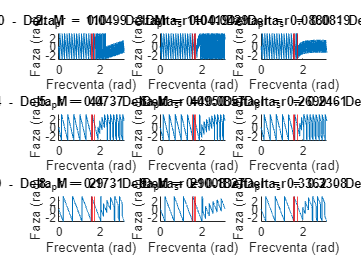


%Figura 18
figure;
subplot(3,3,1);
hold on;
plot(omega,angle(spectre(3,:,2)));
xline([omega_p oc(3,2) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("1. M = 110 - Delta_pr = 0.0499 - Delta_sr = 0.0429");
hold off;

subplot(3,3,2);
hold on;
plot(omega,angle(spectre(3,:,3)));
xline([omega_p oc(3,3) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("2. M = 110 - Delta_pr = 0.0419 - Delta_sr = 0.0819");
hold off;

subplot(3,3,3);
hold on;
plot(omega,angle(spectre(3,:,1)));
xline([omega_p oc(3,1) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("3. M = 110 - Delta_pr = 0.0880 - Delta_sr = 0.0425");
hold off;

subplot(3,3,4);
hold on;
plot(omega,angle(spectre(2,:,2)));
xline([omega_p oc(2,2) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("4. M = 44 - Delta_pr = 0.0737 - Delta_sr = 0.0857");
hold off;

subplot(3,3,5);
hold on;
plot(omega,angle(spectre(2,:,3)));
xline([omega_p oc(2,3) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("5. M = 44 - Delta_pr = 0.0950 - Delta_sr = 0.2461");
hold off;

subplot(3,3,6);
hold on;
plot(omega,angle(spectre(2,:,1)));
xline([omega_p oc(2,1) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("6. M = 44 - Delta_pr = 0.2699 - Delta_sr = 0.0794");
hold off;

subplot(3,3,7);
hold on;
plot(omega,angle(spectre(1,:,2)));
xline([omega_p oc(1,2) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("7. M = 29 - Delta_pr = 0.1731 - Delta_sr = 0.1827");
hold off;

subplot(3,3,8);
hold on;
plot(omega,angle(spectre(1,:,3)));
xline([omega_p oc(1,3) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("8. M = 29 - Delta_pr = 0.1008 - Delta_sr = 0.3308");
hold off;

subplot(3,3,9);
hold on;
plot(omega,angle(spectre(1,:,1)));
xline([omega_p oc(1,1) omega_s], 'r');
xlabel('Frecventa (rad)');
ylabel('Faza (rad)');
title("9. M = 29 - Delta_pr = 0.3362 - Delta_sr = 0.0876");
hold off;

function [Delta_pr,Delta_sr] = PS_PRJ_1_Faza_3a(h,omega_p,omega_s)
    [H, omega] = freqz(h, 1, 1000);

    omega_p_idx = find(omega <= omega_p);
    omega_s_idx = find(omega >= omega_s);

    H_p = abs(H(omega_p_idx));
    H_s = abs(H(omega_s_idx));

    Delta_pr = max(abs(1-H_p));
    Delta_sr = max(H_s);
end

function [omega_p,omega_s,Delta_p] = PS_PRJ_1_Faza_3b(ng,ns) 

%
% Constante
% ~~~~~~~~~
   ng_min = 1 ;  % 333AB
   ng_max = 8 ;  % Restantieri
   ns_min = 1 ;  % numarul primului student in grupa
   ns_max = 30 ; % dimensiunea maxima a grupei
   omega_p_min = 0.2*pi ; 
   omega_p_max = 0.8*pi ; 
   Delta_p_min = 2 ; 	% In procente!
   Delta_p_max = 8 ; 
   ngr = ng_max/ng_min ; 
   nsr = ns_max/ns_min ; 
%
% Parametri specifici pentru N
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   N_min = 30 ; 
   N_max = 400 ;
   rN = N_max/N_min ;
   if ((ngr <= rN) && (rN <= nsr))
      delta = ng_min*ns_max-ng_max*ns_min ;
      a = ns_max*N_min-ns_min*N_max ;
      b = ng_min*N_max-ng_max*N_min ;
   elseif (rN > nsr)
      delta = ng_max*ns_max-ng_min*ns_min ;
      a = ns_max*N_min-ns_min*N_max ;
      b = ng_max*N_max-ng_min*N_min ; 
   else
      delta = ng_min*ns_min-ng_max*ns_max ; 
      a = ns_min*N_min-ns_max*N_max ; 
      b = ng_min*N_max-ng_max*N_min ; 
   end ;
%
% Evaluare si normalizare suprafata de intregi
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   [NG,NS] = meshgrid(ng_min:ng_max,ns_min:ns_max) ; 
   N = round((a*NG+b*NS)/delta) ;
   N = (N'-N_min)/(N_max-N_min) ;
%
% Generare matrice de amestecare
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   A = [12    29    20    11    30    25     6    19
        10    11    25     9    27    13     2    17
        25     1    21    19    23    10     9    15
         1     4     3    27     7    11    25     5
         5    13    27    20    28     2    21    10
         3    15    19     6     4    21     1    24
        13     8    28    14    15    19    27     3
        19    24    22    29    13     7    20    21
        24    18     6     7    10    12    28    23
        17     3    23    12    24     5    30    20
        29    25    24    28    14    23    12    18
         6    12     5     8    18     4    24    28
        30    19     7    23     5    14    26    13
        11    23     8     5    26    30    15     7
        14    22    11    26     6    17     3     4
         9    10    12     4    25    24     8    22
        26     9    17     2     1    22    18     8
        18    30     1    22     8     6    17     2
        16    20     2    24    19     9    22    30
         3    26    13    15     9    16     4     1
         4    14    26    16     2     3    11     9
         7    28     9    25    22     8    14    16
        22     6    10    13     3    26     7    29
        27    17    29    10    12    15    19     6
        28    21    14    17    16    27     5    11
         8     7    16    21    17     1    29    25
        15    27     4    30    21    18    16    12
         2    16    18     1    29    20    23    14
        20     5    30    18    11    28    10    26
        21     2    15     3    20    29    13    27]' ;
%
% Amestecare matrice de intregi
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   for rn=ng_min:ng_max
      N(rn,:) = N(rn,A(rn,:)) ;
   end ; 
   N = N(ng,ns) ;

% Generare omega_p
% ~~~~~~~~~~~~~~~~
   omega_p = omega_p_min + N*(omega_p_max-omega_p_min) ;

% Generare omega_s
% ~~~~~~~~~~~~~~~~
   if exist('rng')
      rng('default') ; 
      rng('shuffle') ; 
   else
      rand('seed',now) ;
   end ;
   NS = pi*(0.03 + 0.12*rand(size(omega_p))) ; 
   omega_s = omega_p + NS ; 

% Generare Delta_p
% ~~~~~~~~~~~~~~~~
   Delta_p = Delta_p_min + N*(Delta_p_max-Delta_p_min) ;
end